clc; clear all; close all;

img_path = fullfile('Codes','fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

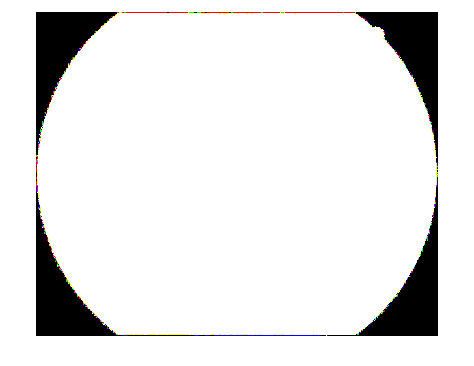

RGB = imread(string(fullfile(img_path, T{1,1})));
RGB=double(RGB);

figure;
imshow(RGB);

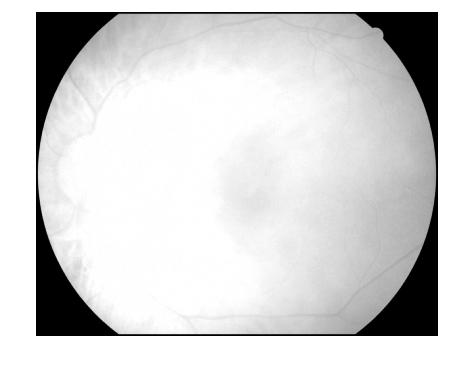

figure;
imshow(RGB(:,:,1),[]);

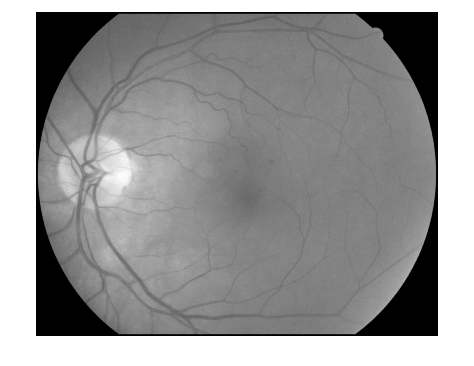

figure;
imshow(RGB(:,:,2),[]);

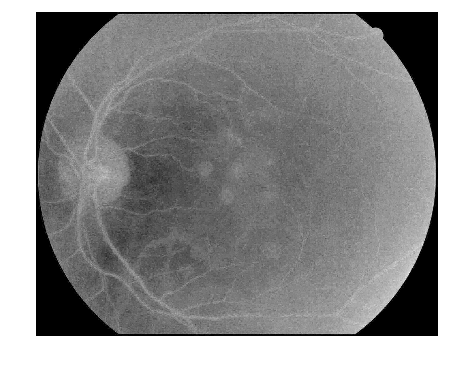

figure;
imshow(RGB(:,:,3),[]);

G=RGB(:,:,2);
G=double(G);
w2 = ones(5);
G = imfilter(G, w2);
G=uint8(G);

thres_2perc = max(G(:))*0.75

thres_2perc = uint8
191

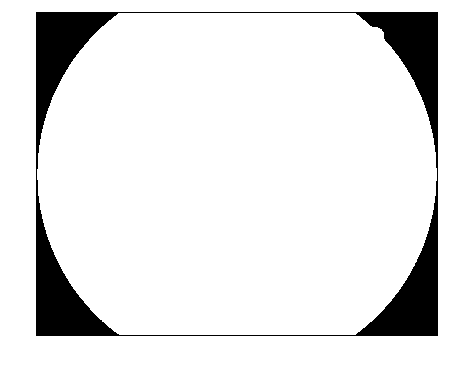

Brightest_2_per=G>=thres_2perc;
imshow(Brightest_2_per,[])


Brightest_2_per=imfill(Brightest_2_per,'holes');
imshow(Brightest_2_per,[])

I=rgb2gray(RGB);
[clusters, centers]=imsegkmeans(RGB(:,:,2),3);
clusterlayers={};

for i=1:length(unique(clusters))
    clusterlayers{i}=clusters==i;
end

### 4. Segmentazioaren emaitza bistaratu (0.5 pt).

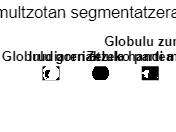

figure;
sgtitle('blastocytes.jpg irudia 3 multzotan segmentatzerakoan lortutako multzoak')
subplot (1, 3, 1);
imshow(clusterlayers{1});
title('Globulu gorriak');
subplot (1, 3, 2);
imshow(clusterlayers{2});
title('Irudiaren atzeko partea');
subplot (1, 3, 3);
imshow(clusterlayers{3});
txt = {'Globulu zuriak','Zelula handi moreak'};
title(txt)

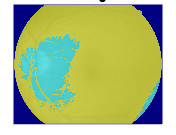


segI=labeloverlay(I,clusters);
figure;
imshow(segI);
txt = {'Gehigarri gisa:','Irudi segmentatua irudi originalean integratua k=3'};
title(txt);

A=G;
[centers, radii, metric] = imfindcircles(A,[80 9000]);
centersStrong5 = centers(1,:); 

Index in position 1 exceeds array bounds.

radiiStrong5 = radii(1);
metricStrong5 = metric(1);
viscircles(centersStrong5, radiiStrong5,'EdgeColor','b');

BINRGB={};
BINRGB=de2bi(G);

BINRGB = 7286544×8 uint8 matrix
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0


figure;
for i=1:8
    subplot(1, 8, i);
    imshow(BINRGB(:,i));
end